clear;

%Default values if not entered in GUI popup
absorbanceSelected = 0;
plotsSelected = 0;
smoothStepsize = 50; %smooth data increment (tied to spectrometer spectral resolution)
timeRangeIn = [];
numdata = 27; %set based on how many files to go through
% spacingtime = 1;
offset = 2; %set offset to ignore this many absorbance plots at start of experiment
offset = offset + 1;
timestepSet = 1; %set a timestep to skip absorbance plots if desired

resultVariables = GUIScript(); %Get values from GUI popup

%If press cancel, stop code
if isempty(resultVariables)
    disp('Canceled');
    return;
end

%Save variables from GUI popup
absorbanceSelected = resultVariables.absorptionYN;
plotsSelected = resultVariables.plotsYN;
Sample = cell2mat(resultVariables.SampleName);
Solvent = cell2mat(resultVariables.SolventName);
ConcentrationAmount = cell2mat(resultVariables.ConcentrationNum);
ConcentrationUnits = resultVariables.SelectedUnit;
StartABSWL = cell2mat(resultVariables.StartWL);
EndABSWL = cell2mat(resultVariables.EndWL);
wavePos = str2double(cell2mat(resultVariables.WavePosition));
timeRangeIn = str2double(cell2mat(resultVariables.TotalTime));
ConcentrationOptions = {'M', 'mM', 'uM', 'nM'};
ConcentrationValues = {1, 1E-3, 1E-6, 1E-9};
if any(strcmp(ConcentrationUnits, ConcentrationOptions))
    concentrationPosition = find(strcmp(ConcentrationUnits, ConcentrationOptions));
    concentration = ConcentrationValues{concentrationPosition};
else
    disp('No concentration set.');
    concentration = 1
end

Solventname = ConcentrationAmount + " " + ConcentrationUnits + " " + Sample + " in " + strrep(Solvent,  '_', ' ');
Solventfilename = ConcentrationAmount + "" + ConcentrationUnits + "" + Sample + "" + strrep(Solvent,  '_', '');
Solventnameminc = Sample + " in " + strrep(Solvent,  '_', ' ');

%Initial concentration
initialConcentration = concentration*str2double(ConcentrationAmount);

%folder processing, finding data based on file heirachy (save under: Samplename/SamplenameSolventConcentration/)
curfolder = pwd;
folderPath = fullfile([curfolder, '/', Sample, '/', Sample, Solvent, ConcentrationAmount, ConcentrationUnits]);
folddirInfo = dir(fullfile(folderPath, '*'));
folddirInfo = folddirInfo(~ismember({folddirInfo.name}, {'.', '..'}));
folders = folddirInfo([folddirInfo.isdir]);
if (isempty(numdata) || isnan(numdata) || numdata > length(folders))
    numdata = length(folders); %if number of data is not set or greater than folders, set to # of folders
end
excitationWLs = cell(1:length(numdata));
foldername = cell(1:length(numdata));
fileData = cell(1:length(numdata));
filePattern = '*.txt';
fileList = cell(1:length(numdata));

%check for laser powers in csv file, needs to be saved in folder with columns in order: wavelength, laser E before, laser E before Std D, laser E after, laser E after Std D
fileNameLaserPower = fullfile([Sample, Solvent, ConcentrationAmount, ConcentrationUnits, 'LaserPowers.csv']);
if exist(fullfile(folderPath, fileNameLaserPower), 'file')
    fileDataLaser = importdata(fullfile(folderPath, fileNameLaserPower));
    LaserPulseEBefore = fileDataLaser.data(1:end,1);
    LaserPulseErrorBefore = fileDataLaser.data(1:end,2);
    LaserPulseEAfter = fileDataLaser.data(1:end,3);
    LaserPulseErrorAfter = fileDataLaser.data(1:end,4);
    CuvetteTransmission = 0.85; %set cuvette transmission here, can add wavelength dependent vector in future if not using quartz cuvettes
    pathlength = 2; %set pathlength based on sample length
    PhotonEnergyMean = (LaserPulseEBefore(1:numdata)+LaserPulseEAfter(1:numdata))/2;
end

%loop through each folder containing a number of absorbance files over time for that given experiment
for i = 1:numdata
    foldername = folddirInfo(i).name;
    expressionWLs = strcat(Sample, Solvent, ConcentrationAmount, ConcentrationUnits, '(\d{1,})nm[A-Z]'); %grab wavelength and ID
    excitationWLs{i} = cell2mat(regexp(foldername, expressionWLs, 'tokens', 'once')); %grab wavelength and add to cell
    ExWaveAP{i} = str2double(excitationWLs{i}); %set to number
    expressionID = strcat(Sample, Solvent, ConcentrationAmount, ConcentrationUnits, num2str(ExWaveAP{i}), 'nm([A-Z])');
    sampleID{i} = cell2mat(regexp(foldername, expressionID, 'tokens', 'once')); % save sample ID to cell
    fileList{i} = dir(fullfile(folderPath, foldername, filePattern)); %get filelist
    expressionName1 = strcat('[^_]*_Absorbance_(\d+)-(\d+)-(\d+)-(\d+)\.txt'); %get the time from first filename
    match1 = regexp(fileList{i}(1).name, expressionName1, 'tokens', 'once');
    intensityData = {}; %create empty cell for data
    %if no time range set, set it from number of files
    if timeRangeIn > length(fileList{i}) | isempty(timeRangeIn) || isnan(timeRangeIn)
        timeRange{i} = length(fileList{i});
    else
        timeRange{i} = timeRangeIn;
    end

    %loop through each file and save the data     
    for j = offset:timeRange{i}-(offset-1) %offset if start of data is delayed
        filename = fileList{i}(j).name;
        fileData = importdata(fullfile(folderPath, foldername, filename));
        dataWithoutHeaders = fileData.data(15:end, :);
        wavelengthColumn = dataWithoutHeaders(:, 1); % Wavelength data
        absColumn = dataWithoutHeaders(:, 2);
        numDistinctColors = length(fileList{i}); %generate number of colours for colourmap
        customColormap = jet(numDistinctColors);
        expression = strcat('[^_]*_Absorbance_(\d+)-(\d+)-(\d+)-(\d+)\.txt'); %set expression for time in filename
        match = regexp(filename, expression, 'tokens', 'once');
        
        StartWLDiff = abs(wavelengthColumn - str2double(StartABSWL)); %find starting wavelength position set from GUI
        [~, closestStartWLIndex] = min(StartWLDiff);
    
        EndWLDiff = abs(wavelengthColumn - str2double(EndABSWL)); %find end wavelength position set from GUI
        [~, closestEndWLIndex] = min(EndWLDiff);
            %save the intensity data from each file and assign the correct time increment to it
            if ~isempty(match)
                hour = str2double(match{1});
                shiftedHour = str2double(match1{1});
                minute = str2double(match{2});
                shiftedMinute = str2double(match1{2}); 
                second = str2double(match{3});
                shiftedSecond = str2double(match1{3}); 
                milliSecond = str2double(match{4});
                shiftedMilliSecond = str2double(match1{4});
                absColumnMin = absColumn(closestStartWLIndex:closestEndWLIndex,:);
                cTime = hour*60*60 + minute*60 + second + milliSecond/1000;
                startTime = shiftedHour*60*60 + shiftedMinute*60 + shiftedSecond + shiftedMilliSecond/1000;
                normTime{i}(j-(offset-1))  = cTime - startTime;
                intensityData{j-(offset-1)} = absColumnMin;
                intensityData{j-(offset-1)} = movmean(intensityData{j-(offset-1)}, smoothStepsize); %smooth data
            end
    end
    %apply timestep
    intensityDataNew = {};
    for l = 1:timestepSet:length(intensityData)
        intensityDataNew{end+1} = intensityData{l};
    end

    normTimeNew{i} = [];
    for w = 1:timestepSet:length(normTime{i})
        normTimeNew{i}(end+1) = normTime{i}(w);
    end

    time{i} = normTimeNew{i};
    increment{i} = time{i}(2)-time{i}(1); %if time increment is fixed and known, can set here, otherwise can calculate from time steps
    time{i} = time{i}-(increment{i}*(offset-1));
    timestep = round(timestepSet/increment{i});

    %grab very first absorbance spectrum from each experiment and save (this is the pure reactant spectrum)
    FirstAbsEach{i} = intensityData{1};
    %grab the last 20 data points and average their absorbance, this is the steady state absorbance (visually check data to make sure reaction shows flat line) 
    AbsSS{i} = (intensityData{end}+intensityData{end-1}+intensityData{end-2}+intensityData{end-3}+intensityData{end-4}+intensityData{end-5}+intensityData{end-6}+intensityData{end-7}+intensityData{end-8}+intensityData{end-9}+intensityData{end-10}+intensityData{end-11}+intensityData{end-12}+intensityData{end-13}+intensityData{end-14}+intensityData{end-15}+intensityData{end-16}+intensityData{end-17}+intensityData{end-18}+intensityData{end-19})/20;
    

    for k = 1:length(intensityData)
            deltaAbs{k} = intensityData{k};
            transMolarAbs = intensityData{1}/initialConcentration;
    end
    
    
    %find correct wavelength index for the desired wavelength to track kinetics
    [~, waveIndex] = min(abs(wavelengthColumn-wavePos));
    MaxIntensity = waveIndex-closestStartWLIndex;
    croppedwavelengthColumn = wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1); %create the cropped wavelength vector

    %if want to plot the absorbance plots over time, can be very costly but is important for checking data, set by GUI
    if plotsSelected == 1
        numy = round(length(time{i})/timestepSet);
        intensityDataAll = cell(length(croppedwavelengthColumn)+1,numy+1);
        intensityDataAll(:,:) = {0};
        intensityDataAll{1,1} = 'Wavelength (nm)';
        intensityDataAll(2:length(croppedwavelengthColumn)+1,1) = num2cell(croppedwavelengthColumn);    
        colorGradient = jet(length(time{i}));
        figure;
        hold on;
        for s = 1:timestepSet:length(time{i})
            intensityDataAll(1,round(s/timestepSet)+2) = num2cell(time{i}(s));    
            intensityDataAll(2:length(croppedwavelengthColumn)+1,(round((s-1)/timestepSet))+2) = num2cell(intensityData{s});
            plot(croppedwavelengthColumn, intensityData{s}, 'Color', colorGradient(s, :));
        end
        hold off;
        xlim([str2double(StartABSWL) str2double(EndABSWL)])
        xlabel('{\it Wavelength} / nm');
        ylabel('Absorbance');
        ylim([-0.05 inf])
        title(Solventname + " with " + excitationWLs{i} + " nm Excitation");
        
        c = colorbar('Location', 'eastoutside');
        c.Label.String = 'Irradiation Time / s';
        colormap jet;
        caxis([0, round(time{i}(end),0)]);
        

        intensityDataAll(1,2) = num2cell(0);
        savename = ['data_' num2str(i) '.csv'];
        writecell(intensityDataAll, savename);
    end

           %some more variables to set based on experiment
           volume = 2E-3;
           AvNum = 6.02214076E23;
           InitialMolecules = initialConcentration*volume*AvNum; %factor of 2 here for tethered molecules with 2 active chromophores

           %check for laser file, if exists, use wavelength data to calculate number of photons for each file
           if exist(fullfile(folderPath, fileNameLaserPower), 'file') 
                EPhotonWL{i} = ExWaveAP{i}*10^-9;
                Np{i} = 20*(transpose(PhotonEnergyMean(i,1))*(10^-6)*EPhotonWL{i}*CuvetteTransmission*time{i})/((6.626*10^-34)*(299792458)); %number of photons
           end
    
    %save different information for each experiment, in form of:
    for l = 1:length(intensityData)
            deltaAbsFull{i}(l) = abs(FirstAbsEach{i}(MaxIntensity)-deltaAbs{l}(MaxIntensity));
            Conversion{i}(l) = abs(FirstAbsEach{i}(MaxIntensity)-deltaAbs{l}(MaxIntensity))/FirstAbsEach{i}(MaxIntensity);
            
    end
        
        model = @(a,t) (a(1)/((a(1))+a(2)))*(1 - exp(-(a(1)+a(2))*t)); %Rate equation modelled
        beta0 = [0.02 0.1];
        pLn{i} = fitnlm(time{i}, Conversion{i}, model, beta0);
        LnFitParameters{i} =  pLn{i}.Coefficients.Estimate; %set the rate coefficients to variable and save to cell for each experiment

    textLoop = [num2str(i),' done'];
    disp(textLoop) %notify progress after each experiment loop here
end

1 done
2 done
3 done
4 done
5 done
6 done
7 done
8 done
9 done



samplesUnique = unique(sampleID); %find unique experiments
repeatSamples = length(samplesUnique); %find repeat experiments #

colormap(jet);

    if iscellstr(excitationWLs)
      uniqueExcitationWLs = cellfun(@str2num, unique(excitationWLs));
    else
      uniqueExcitationWLs = unique(excitationWLs);
    end
    numUniqueWLs = numel(uniqueExcitationWLs); %# of unique wavelengths

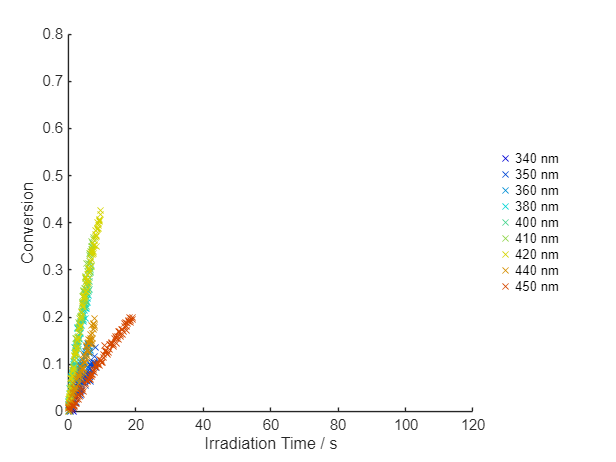

    %graphing kinetics, add section break here for running this section after edits without rerunning first section

    %full kinetic
    figure;
    hold on;
    
    colormap(jet);
    
    if iscellstr(excitationWLs)
      uniqueExcitationWLs = cellfun(@str2num, unique(excitationWLs));
    else
      uniqueExcitationWLs = unique(excitationWLs);
    end
    numUniqueWLs = numel(uniqueExcitationWLs);
    
    for n = 1:3:numdata-2
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        lnscat = scatter(time{n}, Conversion{n}, "x", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
    end    
    for n = 2:3:numdata-1
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        lnscat = scatter(time{n}, Conversion{n}, "x", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
    end   
    for n = 3:3:numdata
        currentItem = str2num(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 

        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;

        lnscat = scatter(time{n}, Conversion{n}, "x", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
    end   

    n=1;
    legendEntries = [];
    legendNames = {};
    for n = 1:repeatSamples:numdata
        currentItem = str2double(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 
        name{n} = [excitationWLs{n}  ' nm '];
        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;
        h = scatter(time{n}, Conversion{n}, "x", 'MarkerEdgeColor', colorToUse, "DisplayName", excitationWLs{n} + " nm " + sampleID{n});
        legendEntries = [legendEntries, h];
        legendNames = [legendNames, name{n}];
    end

        hold off;

    xlabel("Irradiation Time / s");
    ylabel("Conversion") %at " + wavePos + " nm");
    xlim([0 120+0.01]);
    ylim([0 0.8]);
    legend(legendEntries, legendNames, "Location","eastoutside", box="off")

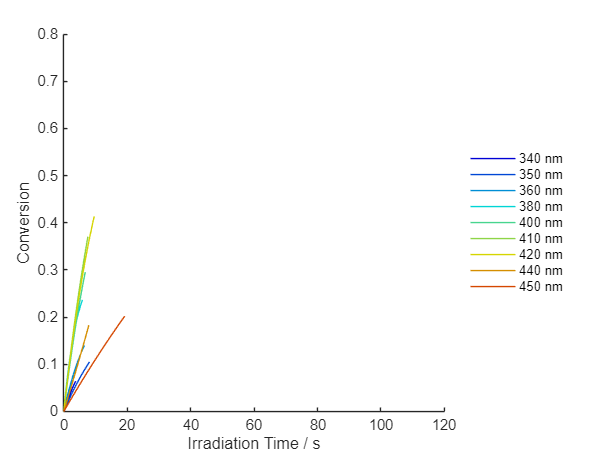


    %full kinetic fits
    figure;
    hold on;
    
    colormap(jet);
    
    if iscellstr(excitationWLs)
      uniqueExcitationWLs = cellfun(@str2num, unique(excitationWLs));
    else
      uniqueExcitationWLs = unique(excitationWLs);
    end
    numUniqueWLs = numel(uniqueExcitationWLs);
    
    for n = 1:numdata
        currentItem = str2double(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 
        name{n} = [excitationWLs{n}  ' nm '];
        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;
        ypredict{n} = predict(pLn{n},transpose(time{n}));
        lnfig = plot(time{n}, ypredict{n}, color=colorToUse);
        set(get(get(lnfig(1), 'Annotation'), 'LegendInformation'), 'IconDisplayStyle', 'off');
    end    
    
    n=1;
    legendEntries = [];
    legendNames = {};
    for n = 1:repeatSamples:numdata
        currentItem = str2double(excitationWLs{n});
        colorIndex = find(uniqueExcitationWLs == currentItem); 
        name{n} = [excitationWLs{n}  ' nm '];
        colormap_colors = jet(numUniqueWLs);
        colorToUse = colormap_colors(colorIndex, :)/1.20;
        h2 = plot(time{n}, ypredict{n}, color=colorToUse);
        legendEntries = [legendEntries, h2];
        legendNames = [legendNames, name{n}];
    end
    
    xlabel('Irradiation Time / s');
    ylabel("Conversion");
    xlim([0 120+0.01]);
    ylim([0 0.8]);
    legend(legendEntries, legendNames, "Location","eastoutside", box="off")
    
    hold off;

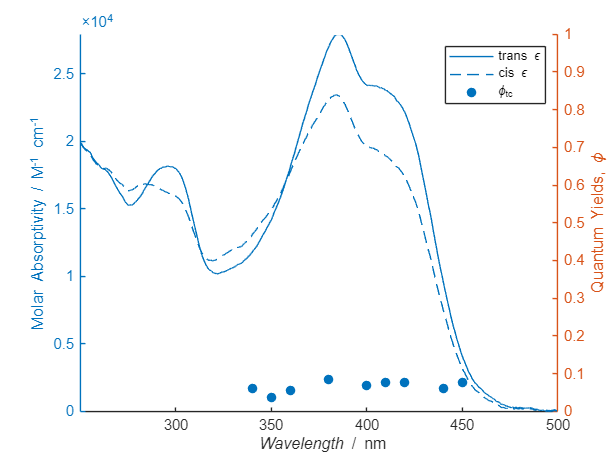

%calculations and more graphs section
AbsAPAv = zeros(length(FirstAbsEach{1}),1);
samples = zeros(length(numdata));
InitialGradientEach = zeros(length(numdata));

%create averaged absorbance from the initial absorbance of each experiment
for aa = 1:numdata
    AbsAPAv = AbsAPAv + FirstAbsEach{aa};
    samples(aa) = sampleID{aa};
end
AbsAPAv = (AbsAPAv-min(AbsAPAv))/numdata;
AbsAPAvA = AbsAPAv;
AbsAPAv = (AbsAPAv)/(concentration*str2double(ConcentrationAmount));

    for u = 1:numdata
        LnTripk1(u) = LnFitParameters{u}(1,1);
        LnTripk2(u) = LnFitParameters{u}(2,1);
        avgExWaveAP(u) = ExWaveAP{u};
    end

    avgExWaveAP = reshape(avgExWaveAP, [], numUniqueWLs);
    UniqueExWaveAP = avgExWaveAP(1,1:numdata/repeatSamples);
    exwavelengths = [ExWaveAP{:}]*10^-9;

    %sort rate coefficient k1      
    LnTripk1Matrix = reshape(LnTripk1(1,1:numdata), repeatSamples, []);
    LnTripk1Avg = mean(LnTripk1Matrix,1);
    LnTripk1UpperError = max(LnTripk1Matrix,[],1) - LnTripk1Avg;
    LnTripk1LowerError = LnTripk1Avg - min(LnTripk1Matrix,[],1);

    %sort rate coefficient k2   
    LnTripk2Matrix = reshape(LnTripk2(1,1:numdata), repeatSamples, []);
    LnTripk2Avg = mean(LnTripk2Matrix,1);
    LnTripk2UpperError = max(LnTripk2Matrix,[],1) - LnTripk2Avg;
    LnTripk2LowerError = LnTripk2Avg - min(LnTripk2Matrix,[],1);

    %find concentrations at steady state for trans and cis isomers
    transC = initialConcentration*(LnTripk2Avg./(LnTripk1Avg+LnTripk2Avg));
    transC = transC(1,1:numdata/repeatSamples);
    cisC = initialConcentration*(LnTripk1Avg./(LnTripk1Avg+LnTripk2Avg));
    cisC = cisC(1,1:numdata/repeatSamples);
    cisCLowerError = cisC.*sqrt((LnTripk2LowerError./LnTripk2Avg).^2+(LnTripk1LowerError./LnTripk1Avg).^2);
    cisCUpperError = cisC.*sqrt((LnTripk2UpperError./LnTripk2Avg).^2+(LnTripk1UpperError./LnTripk1Avg).^2);
    totalCcheck = transC + cisC;  %check these add to = intial concentration

    [maxcisC, maxcisCPos] = max(cisC);
    
    epsTraw = zeros(length(FirstAbsEach{1}),numdata);
    AbsSScalcraw = zeros(length(FirstAbsEach{1}),numdata);
    for eee = 1:(numdata)
        epsTraw(:,eee) = (FirstAbsEach{eee})/(concentration*str2double(ConcentrationAmount));
        AbsSScalcraw(:,eee) = transpose(AbsSS{eee}-min(AbsSS{eee}));
    end
    epsT = reshape(epsTraw, size(epsTraw, 1), repeatSamples, numdata/repeatSamples);
    epsT = mean(epsT,2);
    epsT = reshape(epsT, size(epsTraw, 1), numdata/repeatSamples);
    %absorbance at steady state
    AbsSScalc = reshape(AbsSScalcraw, size(AbsSScalcraw, 1), repeatSamples, numdata/repeatSamples);
    AbsSScalc = mean(AbsSScalc,2);
    AbsSScalc = reshape(AbsSScalc, size(AbsSScalcraw, 1), numdata/repeatSamples);

    %calculate molar absorptivity for cis isomer from the data
    epsC = (AbsSScalc - (epsT.*transC))./cisC;
    for minloop = 1:numdata/repeatSamples
        epsCnew(:,minloop) = epsC(:,minloop);%-min(epsC(:,minloop));
    end
    epsCnew = reshape(epsCnew, size(epsC, 1), numdata/repeatSamples);
    epsCnew = epsCnew - min(epsCnew);
    %find mean value for cis isomer molar absorptivity (just using last 4 wavelengths, data more reliable due to bigger change in absorbance data)
    epsCMean = mean(epsCnew(:,6:9),2);
    epsTMean = mean(epsT,2);

%Trans cis molar absorptivity at excitation wavelength
    for a = 1:numdata/repeatSamples
        [~, WLLocation] = min(abs(wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1) - UniqueExWaveAP(a)));
        EachWLCoord(a) = WLLocation;
        TransEpsatWL(a) = AbsAPAv(WLLocation);
        CisEpsatWL(a) = epsCMean(WLLocation);
    end

%Photon flux equations 
PhotonFlux = (transpose(PhotonEnergyMean).*(10^-6)*20.*exwavelengths)./((6.626*10^-34)*(299792458)); %20 Hz laser
PhotonFluxMatrix = reshape(PhotonFlux(1,1:numdata), repeatSamples, []);
PhotonFluxAvg = mean(PhotonFluxMatrix,1);
PhotonErrorMean = transpose(sqrt((LaserPulseErrorBefore(1:numdata)./LaserPulseEBefore(1:numdata)).^2+(LaserPulseErrorAfter(1:numdata)./LaserPulseEAfter(1:numdata)).^2));
PhotonErrorMatrix = reshape(PhotonErrorMean(1,1:numdata), repeatSamples, []);
PhotonErrorAvg = mean(PhotonErrorMatrix,1);

%Quantum yield equations
QYk1 = LnTripk1Avg./(PhotonFluxAvg.*(TransEpsatWL*log(10)*10^3)/AvNum);
QYk1LowerError = sqrt((LnTripk1LowerError./LnTripk1Avg).^2+(PhotonErrorAvg.^2)).*QYk1;
QYk1UpperError = sqrt((LnTripk1UpperError./LnTripk1Avg).^2+(PhotonErrorAvg.^2)).*QYk1;

%plot quantum yields
figure
hold on
yyaxis left
plot(wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1), AbsAPAv(:,:), LineStyle="-");
plot(wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1), epsCMean(:,:), LineStyle="--");
hold off
ylabel('Molar Absorptivity / M^{-1} cm^{-1}');
ylim([0 max(AbsAPAv)])
yyaxis right
hold on
plot(UniqueExWaveAP, QYk1, 'o', 'color', '#0072BD', 'MarkerFaceColor', '#0072BD');
errorbar(UniqueExWaveAP, QYk1, QYk1LowerError, QYk1UpperError, 'o', 'color', '#0072BD');
hold off
xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])
xlabel('{\it Wavelength} / nm');
ylabel('Quantum Yields, \phi');
xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])
ylim([0 1])
legend("trans \epsilon","cis \epsilon", "\phi_{tc}", "","Location","northeast")

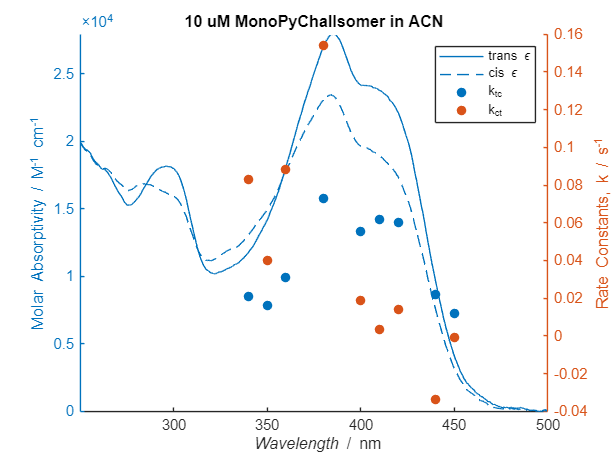


%plot raw rate constants
figure
hold on
yyaxis left
plot(wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1), AbsAPAv(:,:), LineStyle="-");
plot(wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1), epsCMean(:,:), LineStyle="--");
hold off
ylabel('Molar Absorptivity / M^{-1} cm^{-1}');
ylim([0 max(AbsAPAv)])
yyaxis right
hold on
plot(UniqueExWaveAP, LnTripk1Avg, 'o', 'color', '#0072BD', 'MarkerFaceColor', '#0072BD');
errorbar(UniqueExWaveAP, LnTripk1Avg, LnTripk1LowerError, LnTripk1UpperError, 'o', 'color', '#0072BD');
plot(UniqueExWaveAP, LnTripk2Avg, 'o', 'color', '#D95319', 'MarkerFaceColor', '#D95319');
errorbar(UniqueExWaveAP, LnTripk2Avg, LnTripk2LowerError, LnTripk2UpperError, 'o', 'color', '#D95319');
hold off
xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])
xlabel('{\it Wavelength} / nm');
ylabel('Rate Constants, k / s^{-1}');
xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])
title(Solventname)
legend("trans \epsilon", "cis \epsilon", "k_{tc}", "", "k_{ct}", "", "Location","northeast")

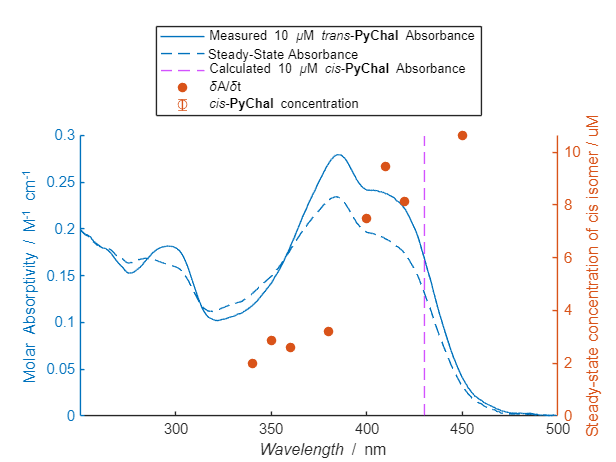


%plot cis isomer concentration at steady state
figure;
yyaxis left
hold on
plot(wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1), AbsAPAvA(:,:));
plot(wavelengthColumn(closestStartWLIndex:closestEndWLIndex,1), epsCMean(:,:)*initialConcentration);
xline(wavelengthColumn(waveIndex,1), LineStyle="--",Color="#c109ff");
ylabel('Molar Absorptivity / M^{-1} cm^{-1}');
xlim([str2double(StartABSWL) str2double(EndABSWL)])
hold off
yyaxis right
hold on;
ymax3 = max(cisC);
ylim([0 ymax3+ymax3/10])
plot(UniqueExWaveAP, cisC*10^6, 'o', 'color', '#D95319', 'MarkerFaceColor', '#D95319');
errorbar(UniqueExWaveAP, cisC*10^6, cisCLowerError*10^6, cisCUpperError*10^6, 'o', 'color', '#D95319');
hold off;
xlabel('{\it Wavelength} / nm');
ylabel("Steady-state concentration of cis isomer / uM");
ylim([0 inf])
xlim([wavelengthColumn(closestStartWLIndex) wavelengthColumn(closestEndWLIndex)])

legend("Measured 10 {\mu}M {\ittrans}-{\bfPyChal} Absorbance", "Steady-State Absorbance", "Calculated 10 {\mu}M {\itcis}-{\bfPyChal} Absorbance","{\deltaA/\deltat}", "{\itcis}-{\bfPyChal} concentration", "Location","northoutside",Interpreter="tex")

%GUI code
function variables = GUIScript()

    fig = uifigure('Name', 'Please fill out the entries below', 'Position', [100, 100, 400, 350]);

    options = {'Action Plot', 'Abs Plots'};
    concentrationOptions = {'M', 'mM', 'uM', 'nM'};
    numOptions = numel(options);
    variables = struct();

    checkBoxLabel = uilabel(fig, 'Text', 'Show:', 'Position', [230, 320, 150, 22]);
    checkboxWidth = 120;
    checkboxHeight = 22;
    checkboxes = gobjects(1, numOptions);
    for i = 1:numOptions
        checkboxes(i) = uicheckbox(fig, 'Text', options{i}, 'Position', [230, 320 - 25 * i, checkboxWidth, checkboxHeight]);
    end
    
    textbox1Label = uilabel(fig, 'Text', 'Sample name:', 'Position', [50, 300, 150, 22]);
    textbox1 = uitextarea(fig, 'Position', [50, 280, 150, 22]);

    textbox2Label = uilabel(fig, 'Text', 'Solvent used:', 'Position', [50, 250, 100, 22]);
    textbox2 = uitextarea(fig, 'Position', [50, 230, 100, 22]);

    textbox3Label = uilabel(fig, 'Text', 'Concentration:', 'Position', [50, 200, 80, 22]);
    textbox3 = uitextarea(fig, 'Position', [50, 180, 50, 22]);
    
    textbox4Label = uilabel(fig, 'Text', 'Start WL:', 'Position', [180, 200, 60, 22]);
    textbox4 = uitextarea(fig, 'Position', [180, 180, 60, 22]);
    
    textbox5Label = uilabel(fig, 'Text', 'End WL:', 'Position', [250, 200, 60, 22]);
    textbox5 = uitextarea(fig, 'Position', [250, 180, 60, 22]);

    textbox6Label = uilabel(fig, 'Text', 'dA WL:', 'Position', [320, 200, 60, 22]);
    textbox6 = uitextarea(fig, 'Position', [320, 180, 60, 22]);

    textbox7Label = uilabel(fig, 'Text', 'Total Time:', 'Position', [250, 150, 80, 22]);
    textbox7 = uitextarea(fig, 'Position', [250, 130, 60, 22]);

    dropdownLabel = uilabel(fig, 'Text', '', 'Position', [100, 200, 50, 22]);
    dropdown = uidropdown(fig, 'Items', concentrationOptions, 'Position', [100, 180, 50, 22]);
    
    confirmButton = uibutton(fig, 'Text', 'Confirm', 'Position', [50, 20, 70, 30], 'ButtonPushedFcn', @(btn, event) confirmSelection());
    cancelButton = uibutton(fig, 'Text', 'Cancel', 'Position', [130, 20, 70, 30], 'ButtonPushedFcn', @(btn, event) cancelSelection());

    loadState();
    
    function confirmSelection()
        variables.absorptionYN = checkboxes(1).Value;
        variables.plotsYN = checkboxes(2).Value;

        variables.SampleName = textbox1.Value;
        variables.SolventName = textbox2.Value;
        variables.ConcentrationNum = textbox3.Value;
        variables.StartWL = textbox4.Value;
        variables.EndWL = textbox5.Value;
        variables.WavePosition = textbox6.Value;
        variables.TotalTime = textbox7.Value;

        variables.SelectedUnit = dropdown.Value;
        
        save('guiStateIso.mat', 'variables');
        close(fig);
    end

    function cancelSelection()
        disp('Aborted');
        close(fig);
        variables = [];
        return;
    end

    
    function loadState()
        if exist('guiStateIso.mat', 'file')
            load('guiStateIso.mat', 'variables');
            
            checkboxes(1).Value = variables.absorptionYN;
            checkboxes(2).Value = variables.plotsYN;

            textbox1.Value = variables.SampleName;
            textbox2.Value = variables.SolventName;
            textbox3.Value = variables.ConcentrationNum;
            textbox4.Value = variables.StartWL;
            textbox5.Value = variables.EndWL;
            textbox6.Value = variables.WavePosition;
            textbox7.Value = variables.TotalTime;

            dropdown.Value = variables.SelectedUnit;
        end
    end
    
    movegui(fig, 'center');
    uiwait(fig);

end







